# **SYST 662 Team 1 Project**

## **Questions**

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence? 

(Q2) What fraction of trips are re-routed due to road conditions?

## **Notes**

<insert header notes here>

## **Script:**

close all;
clear all; %#ok<CLALL> 

% Declare Answer Variables
Q1_predictive_routing_savings_value = " NOT"; % Replace with "" (empty string) if true
Q2_fraction_of_trips_rereouted_value = 0;

% Load Data Files
load EastCoast.mat
load Supporting_Data_Team_01.mat

% Set Up Simulation
% TODO all code here

## TUTORIAL CODE ONLY - remove after implementing our solution

### Computing times through the graph

The ITS problem requires computing travel times through the road network (graph).  The code below will compute the travel times for five random trips through the baseline graph.

% Define unit conversion
mins_per_hr = 60;
% Select start and stop points for tests
% Randomly selects 5 trips
trips = randi(numnodes(G),5,2); % numnodes(G) returns the # of nodes in the graph

%trips = randi(numnodes(G),numnodes(G),2); % TESTING ALL POSSIBILITIES %
%DONT DO THIS LOL - TAKES A VERY LONG TIME

for k=1:size(trips,1) % size(trips,1) returns the number of rows in the matrix
    % Get the names of the start and end points
    start_name = G.Nodes.Name(trips(k,1)); % Returns a cell array
    end_name   = G.Nodes.Name(trips(k,2)); % Returns a cell array
    fprintf('Trip %d : From [%s] to [%s]\n', ...
        k, start_name{1}, end_name{1});
end

Trip 1 : From [US130@CR551_N] to [US62/OH7@AlbSt]
Trip 2 : From [US209_N/PA125_S] to [I-516@MilSt]
Trip 3 : From [I-81@5] to [US460@+x59]
Trip 4 : From [US22@US40_W&US40@US22_W&OH93@US40_W] to [US30@BaiBlvd]
Trip 5 : From [US219/US250/WV55/WV92@+X053(US219)] to [US21_S/SC200_S]


% Change the graph weights to equal the travel time
% Note the use of vectorization to speed up the computation
G.Edges.Weight = G.Edges.Distance ./ G.Edges.Speed * mins_per_hr;
% Evaluate the trips using the baseline graph
for k=1:size(trips,1)  
    % Find the shortest path from start to end. Indicate all the 
    % Weights are positive to support a faster algorithm
    [path_nominal , t_nominal] = shortestpath(G,trips(k,1),trips(k,2),...
         'method','positive'); 
     
    % Get all the node IDs (numbers) for each node in the path
    node_ids = findnode(G,path_nominal);
    % Get all the edge IDs (numbers) for each edge in the path
    edge_ids = findedge(G, node_ids(1:end-1), node_ids(2:end));
    % Compute the distance of the path by summing the length of each edge
    nominal_distance = sum(G.Edges.Distance( edge_ids ) );
    % Compute the average speed along the path
    average_speed = mean(G.Edges.Speed( edge_ids ) );
    
    fprintf('Trip %2d - %6.2f miles, travel time = %6.2f mins, average speed = %6.2f\n', ...
        k, nominal_distance, t_nominal, average_speed);
end

Trip  1 - 377.83 miles, travel time = 350.57 mins, average speed =  64.07
Trip  2 - 982.12 miles, travel time = 1009.43 mins, average speed =  58.79
Trip  3 - 335.50 miles, travel time = 376.82 mins, average speed =  55.25
Trip  4 - 408.05 miles, travel time = 379.69 mins, average speed =  64.10
Trip  5 - 383.22 miles, travel time = 412.67 mins, average speed =  56.18


### Generating Random Speeds

The problem calls for generating random speeds.  Assume we know the speeds are Normally distributed with a mean of 50 mph and a standard deviation of 5 mph.  We can create a distribution that generates the specific random variable using the command below. **Note, each team will need to determine the speed distributions using the provided data.**

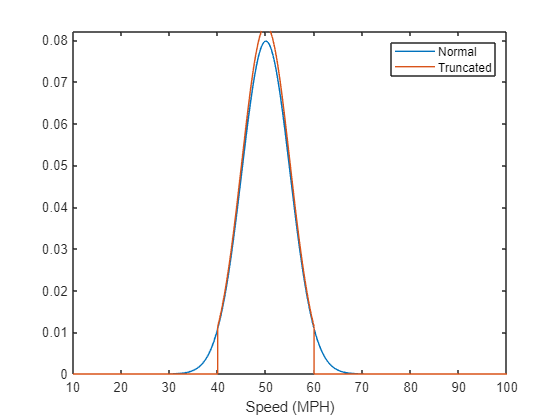

pd = makedist('Normal',50,5);
pd_trunc  = truncate(pd,40, 60);
fplot(@(x) pdf(pd,x),[10 100]);
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off
legend('Normal','Truncated')

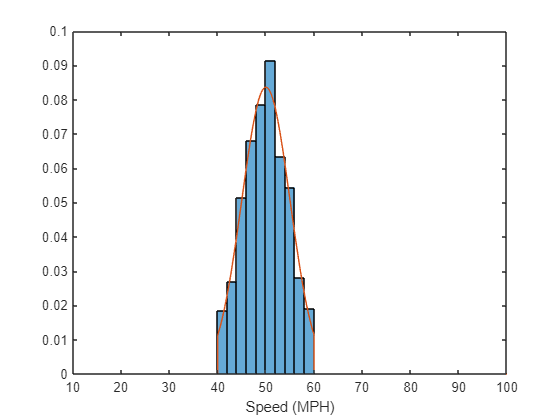

data = random(pd_trunc,[1000,1]);
histogram(data,'Normalization','pdf')
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off

## **Result:**

% Output answers to Q1 and Q2
fprintf('(Q1) On average, does predictive routing save more than 5%% of the trip time to a 95%% confidence?');

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence?

fprintf('\tQ1: On average, predictive routing does%s save more than 5%% of the trip time to a 95% confidence.', Q1_predictive_routing_savings_value);

	Q1: On average, predictive routing does NOT save more than 5% of the trip time to a 95

fprintf('(Q2) What fraction of trips are re-routed due to road conditions?');

(Q2) What fraction of trips are re-routed due to road conditions?

fprintf('\tQ2: %0.4f%% of trips are re-routed due to road conditions.\n\n', Q2_fraction_of_trips_rereouted_value);

	Q2: 0.0000% of trips are re-routed due to road conditions.



## Unit Testing

fprintf('The following output contains results from the Verification and Validation Plan.');

The following output contains results from the Verification and Validation Plan.

### Computing Travel Times:

% Test 1: Check the weights of the edges
%{
for i=1:numedges(G)
    weight = G.Edges.Distance(i) / G.Edges.Speed(i) * mins_per_hr;
    assert(G.Edges.Weight(i) == weight, 'Weight of edge %d FAILED', i);
end

% Test 2: Check the shortest path and travel time for each trip
for j=1:size(trips,1)
    [path,t] = shortestpath(G,trips(j,1),trips(j,2),'method','positive');
    assert(~isempty(path), 'Path FAILED: Path %d is empty', j);
    assert(t>=0, 'Travel Time FAILED: Trip %d is negative', j);
end
%}

### Generating Trips:

%{
confidence_interval = 0.95;
mu = 0;
sigma = 0;
uniqueness = 0;
trips = genlogntrips(G,size(trips,1),confidence_interval,mu,sigma,uniqueness);

% Test 3: Check size of Trips
assert(size(trips,1) == size(trips,1), 'Number of Trips FAILED: %d', size(trips)));

% Test 4: Check Distance Minimum
assert(min(trips(:,3)) >= 0, 'Distance Value FAILED');

% Test 5: Check Distance Maximum
assert(max(trips(:,3)) <= 2*mu*100, 'Distance Maximum FAILED');

% Test 6: Check Confidence Interval
assert(mean(trips(:,3)) > mu*100*(1-confidence_interval), 'Confidence Interval FAILED.');
%}

Completed All Test Cases

disp('ALL TEST CASES PASS');

ALL TEST CASES PASS
